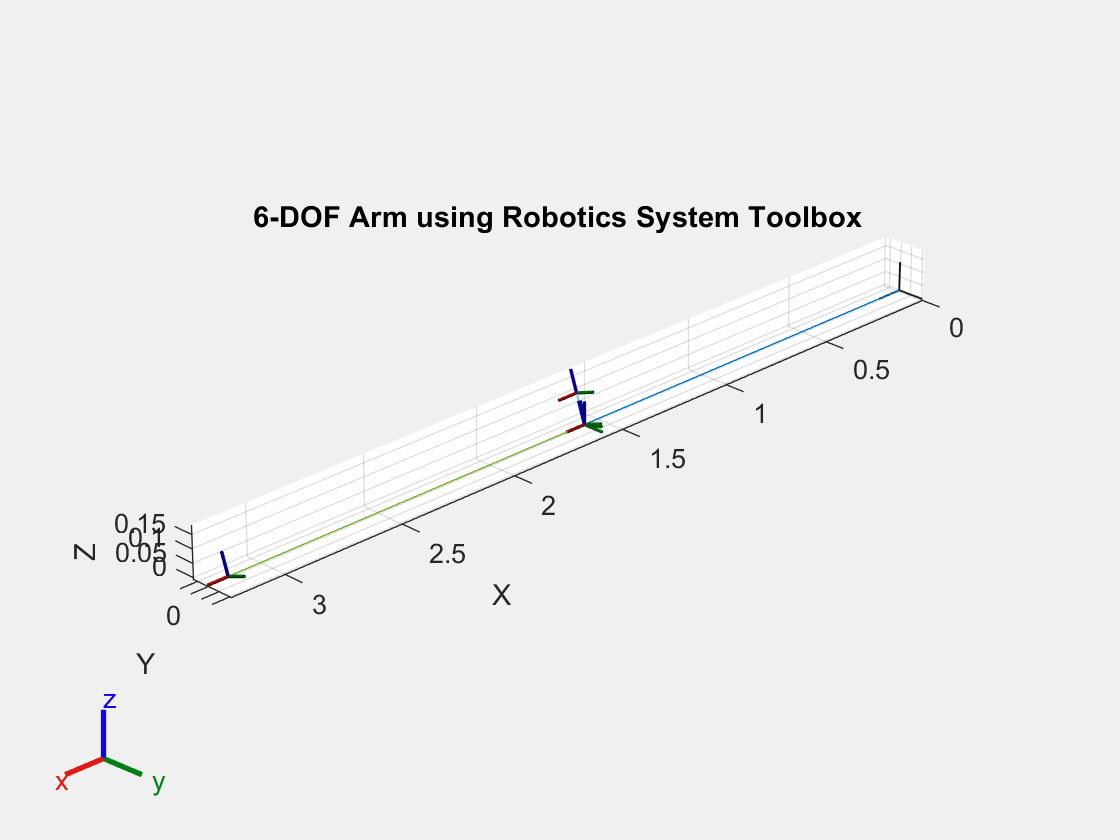

% Create a rigidBodyTree model using DH parameters
robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);

% DH Parameters [alpha, a, d, theta]
dhParams = [...
     pi/2,     0,      0,       0;      % Link 1
     0,     0.2335,    0,       0;      % Link 2
     0,     0.111,     0,       0;      % Link 3
     pi/2,    0,        0,      0;      % Link 4
    -pi/2,    0,        0,      0;      % Link 5
     0,       0,     0.1098,    0];     % Link 6

% Add each link
prevBody = robot.Base;
for i = 1:size(dhParams,1)
    body = rigidBody(['body' num2str(i)]);
    joint = rigidBodyJoint(['joint' num2str(i)], 'revolute');

    % Use classic DH convention
    setFixedTransform(joint, dhParams(i,:), 'dh');
    body.Joint = joint;
    addBody(robot, body, prevBody.Name);
    prevBody = body;
end

% Show model
figure;
show(robot);
title('6-DOF Arm using Robotics System Toolbox');
view(135, 25);
axis equal; grid on;

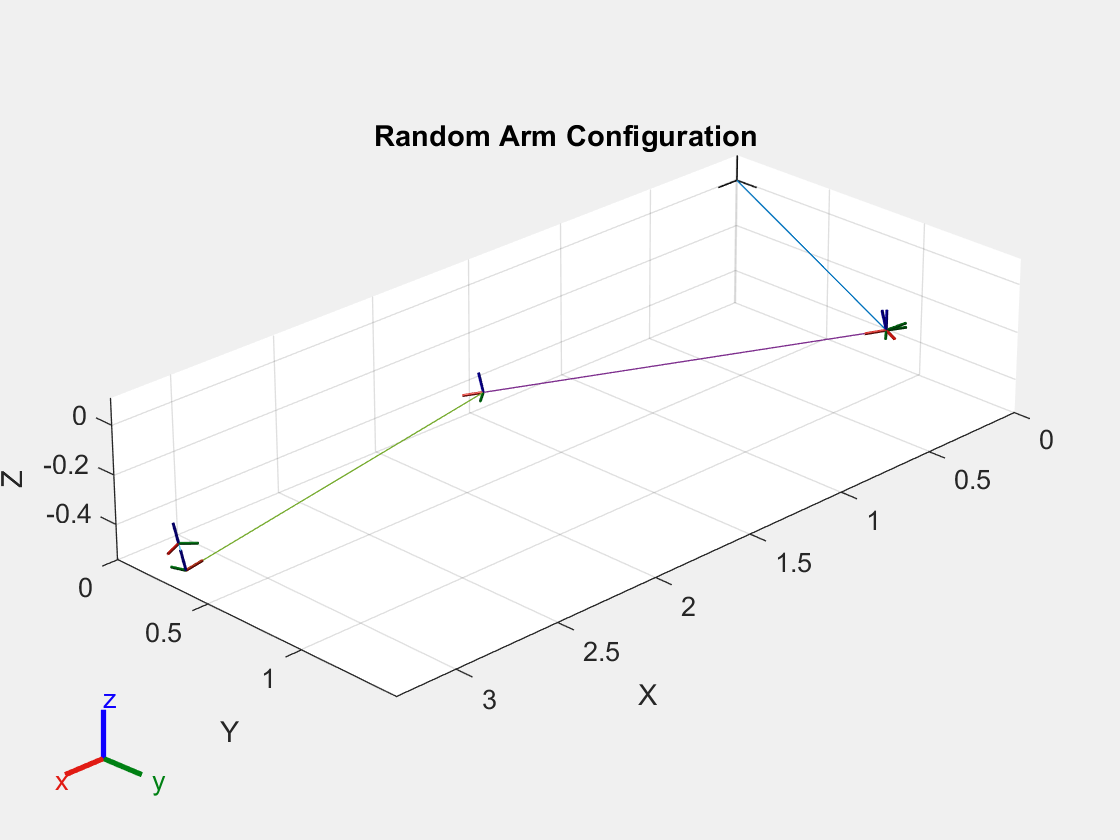


% Optional: Animate a random configuration
randomConfig = randomConfiguration(robot);
figure;
show(robot, randomConfig, 'PreservePlot', false);
title('Random Arm Configuration');
view(135, 25);
axis equal; grid on;

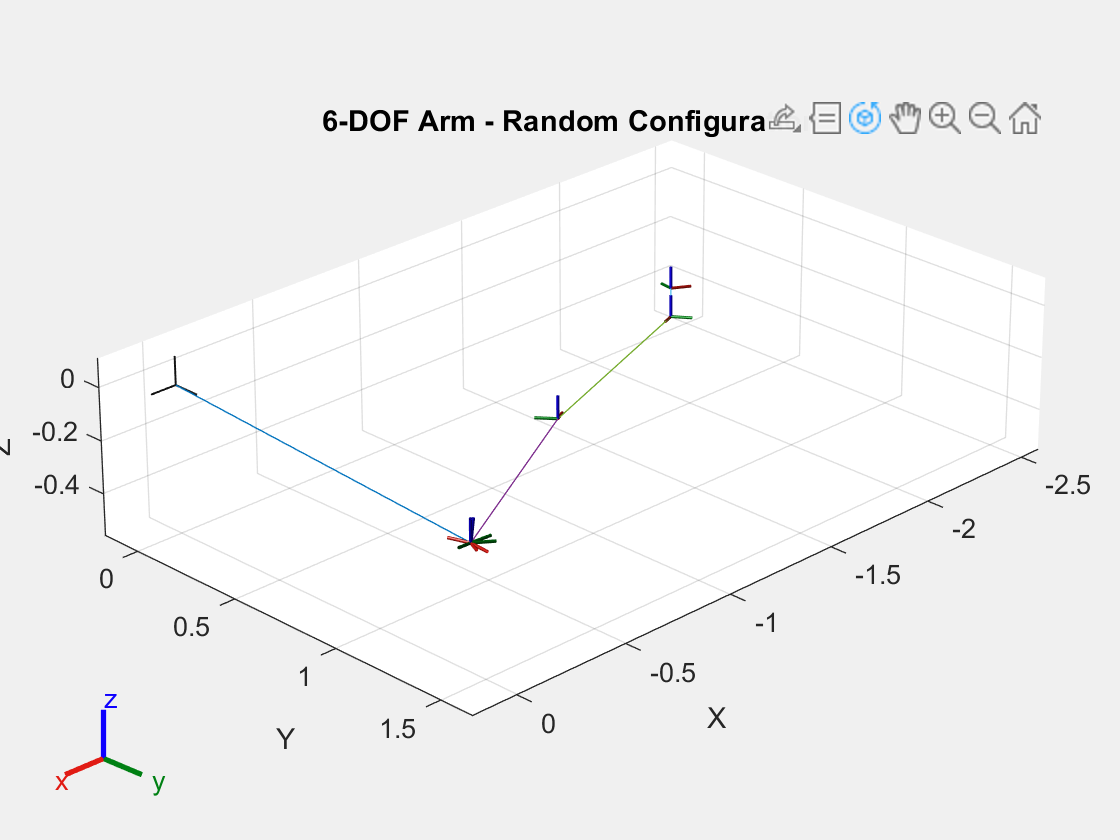

% Create a 6-DOF robot using classic DH parameters (MathWorks RST)
robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);

% Define the DH table [alpha, a, d, theta] in radians/meters
dhParams = [...
     pi/2,     0,      0,       0;      % Joint 1 (Base yaw)
     0,     0.2335,    0,       0;      % Joint 2 (Shoulder)
     0,     0.111,     0,       0;      % Joint 3 (Elbow)
     pi/2,    0,        0,      0;      % Joint 4 (Wrist yaw)
    -pi/2,    0,        0,      0;      % Joint 5 (Wrist pitch)
     0,       0,     0.1098,    0];     % Joint 6 (Wrist roll + tool)

% Add joints and bodies to the robot
prevBody = robot.Base;
for i = 1:6
    body = rigidBody(['body' num2str(i)]);
    joint = rigidBodyJoint(['joint' num2str(i)], 'revolute');
    setFixedTransform(joint, dhParams(i,:), 'dh');  % classic DH
    body.Joint = joint;
    addBody(robot, body, prevBody.Name);
    prevBody = body;
end

% Visualize random pose
figure;
show(robot, randomConfiguration(robot), 'PreservePlot', false);
view(135, 25); axis equal; grid on;
title('6-DOF Arm - Random Configuration');


% Optional: visualize zero config
% show(robot, zeros(1,6));





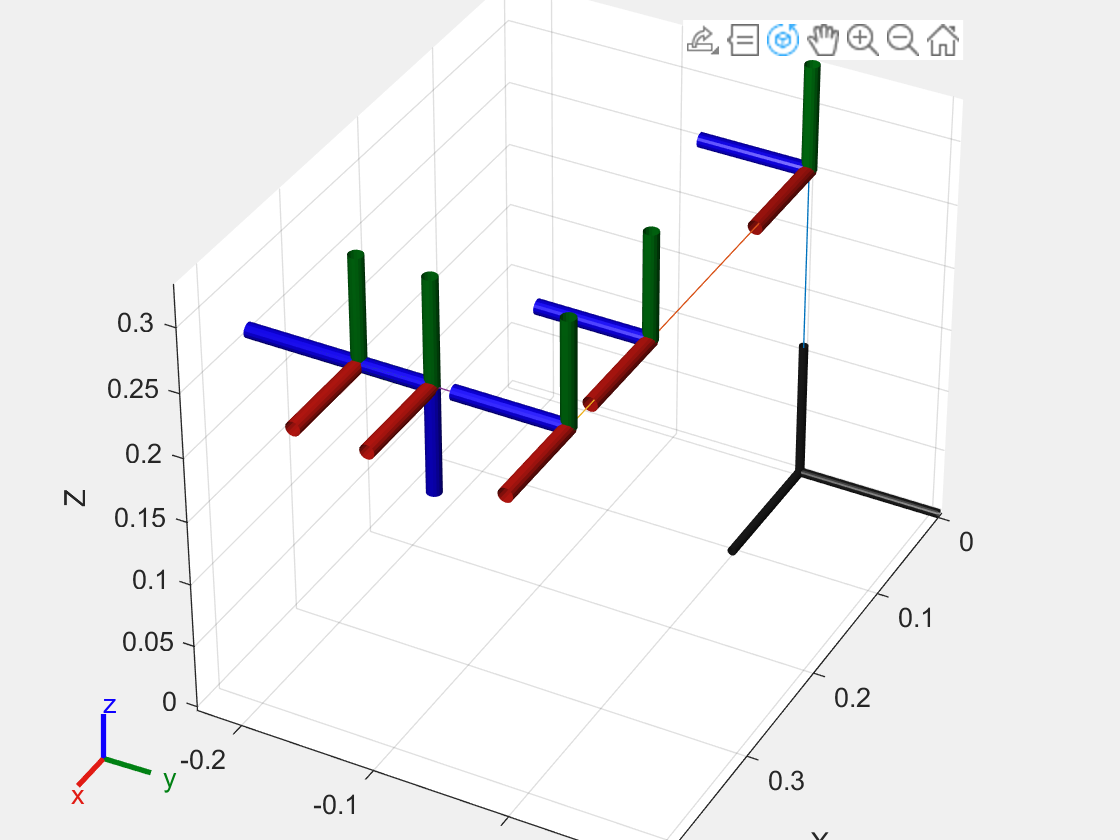


robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);

dhparams = [...
    0     0.250   0       pi/2;
    0     0       0.2335  0;
    0     0       0.111   0;
    0     0.0978  0       pi/2;
    0     0       0      -pi/2;
    0     0.0533  0       0];

for i = 1:6
    body = rigidBody(sprintf('link%d', i));
    joint = rigidBodyJoint(sprintf('joint%d', i), 'revolute');
    
    theta = dhparams(i,1);
    d     = dhparams(i,2);
    a     = dhparams(i,3);
    alpha = dhparams(i,4);

    % Construct transformation using built-in functions
    tform = ...
        trvec2tform([0 0 d]) * ...                  % Translation along Z
        rotm2tform(axang2rotm([1 0 0 alpha])) * ... % Rotation about X
        trvec2tform([a 0 0]);                       % Translation along X

    setFixedTransform(joint, tform);
    body.Joint = joint;

    if i == 1
        addBody(robot, body, 'base');
    else
        addBody(robot, body, sprintf('link%d', i-1));
    end
end

% Show robot
figure;
show(robot);
view(135, 25);
axis equal;
title('6-DOF Arm Visualization (Built-in Functions Only)');

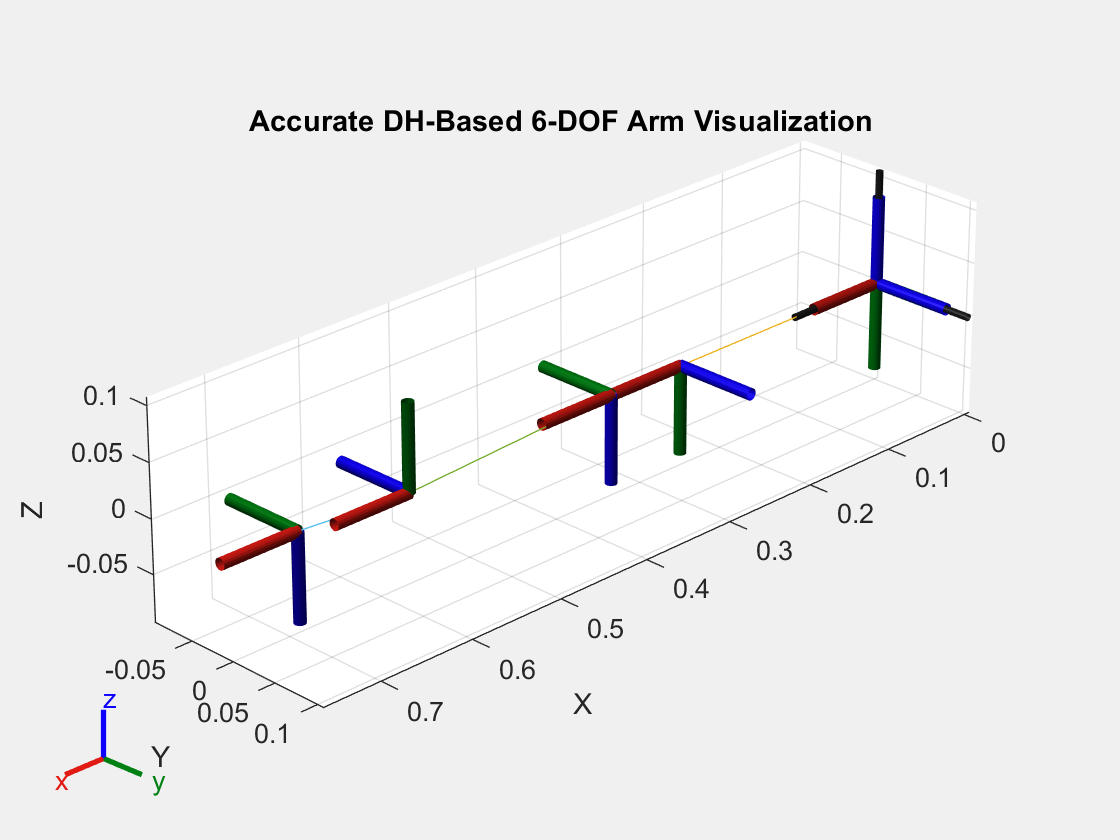


robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);

dhparams = [...
    0     0.00000   0.00000     0;
    0     0.00000   0.00000    -90;
    0     0.00000   0.25000     0;
    0     0.00000   0.08416   -90;
    0     0.01100   0.23350   -90;
    0     0.01200   0.11100    90];

for i = 1:6
    body = rigidBody(sprintf('link%d', i));
    joint = rigidBodyJoint(sprintf('joint%d', i), 'revolute');

    theta = dhparams(i,1);
    d     = dhparams(i,2);
    a     = dhparams(i,3);
    alpha = deg2rad(dhparams(i,4));

    tform = ...
        trvec2tform([0 0 d]) * ...
        rotm2tform(axang2rotm([1 0 0 alpha])) * ...
        trvec2tform([a 0 0]);

    setFixedTransform(joint, tform);
    body.Joint = joint;

    if i == 1
        addBody(robot, body, 'base');
    else
        addBody(robot, body, sprintf('link%d', i-1));
    end
end

% Show the robot
figure;
show(robot);
view(135, 25);
axis equal;
title('Accurate DH-Based 6-DOF Arm Visualization');